# EPC 5 - REPOSIÇÃO

## João Gabriel Santos Custodio

clc, clear, clear all var
load EPC5.mat

#### 1) Selecione os segmentos de dados X1, X2 e X3 para fazer um teste de médias, de modo que as populações de X1 e X2 tenham a mesma média enquanto X1 e X3 tenham médias diferentes, com $\alpha$ = 5% . Use 500 amostras de X1,X2 e X3 para obter o desvio padrão dessas populaç ões, que assim será considerado conhecido.

#### Deve-se plotar os dados utilizados em cada segmento, a pdf das populações usadas no teste com o valor da estatística de teste, o p-valor.

#### Selecione com algum critério o número de amostras da população usado para o teste, analisando seu efeito sobre a confiança da decisão.

Resposta:

Primeiramente será plotado os dados de que temos em Y.

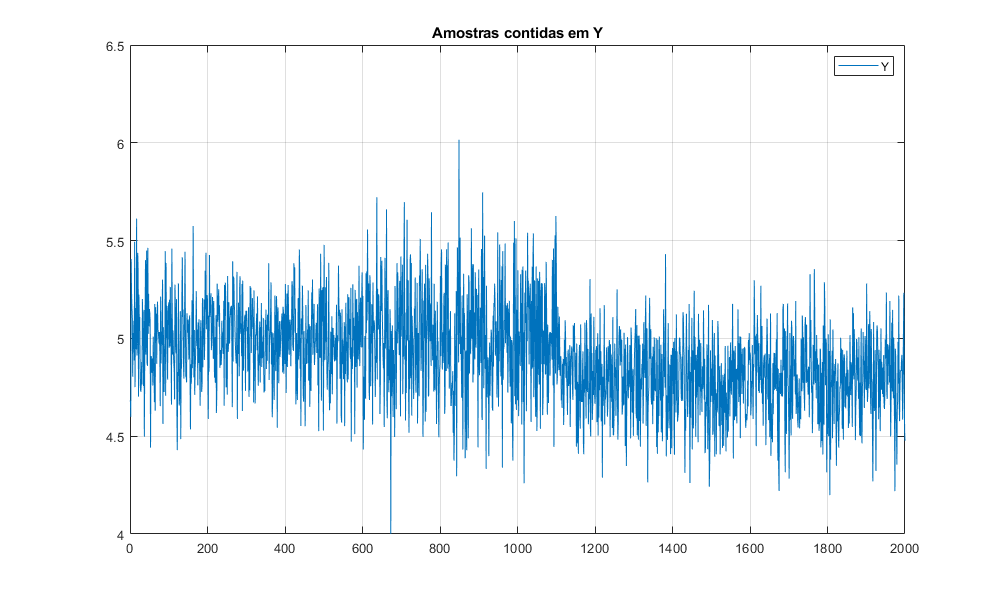

figure;
set(gcf,'position',[10,10,1000,600])
plot(Y);
hold on
%plot([1106,1106], [min(Y), max(Y)], "Color", "red", "LineWidth", 2);
legend("Y")
title("Amostras contidas em Y")
grid;

Com os dados plotados, pode-se fazer a seleção de X1, X2 e X3 para fazer um teste de médias de modo que X1 e X2 tenham a mesma média e X1 e X3 tenham médias diferentes com $\alpha =5$.

X1 = datasample(Y(1:900), 800);
X2 = datasample(Y(1:900), 800);
X3 = datasample(Y(1106:2000), 800);

%calculando as médias
mean_X1 = mean(X1)

mean_X1 = 4.9965

mean_X2 = mean(X2)

mean_X2 = 4.9941

mean_X3 = mean(X3)

mean_X3 = 4.7838

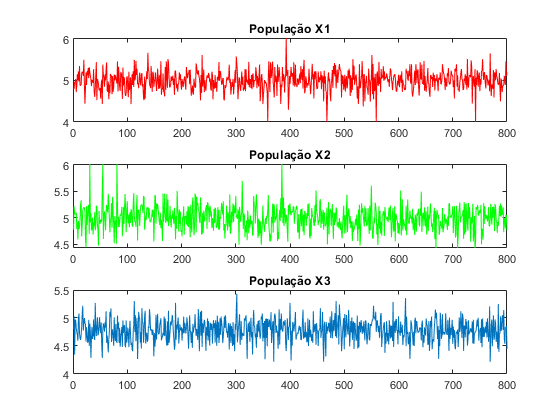

%Plotando dados selecionados

subplot(3,1,1)
plot(X1, "Color", "r")
title('População X1')

subplot(3,1,2)
plot(X2, 'color', "g")
title('População X2')

subplot(3,1,3)
plot(X3)
title('População X3')

Cálculo do desvio padrão

std_X1 = std(datasample(X1, 500))

std_X1 = 0.2142

std_X2 = std(datasample(X2, 500))

std_X2 = 0.2353

std_X3 = std(datasample(X3, 500))

std_X3 = 0.2065

alfa = 0.05;
z_alfa = norminv(1 - alfa)

z_alfa = 1.6449

Temos que a hipótese nula é $H_0 :\mu_1 -\mu_2 =0\;$$H_0 :\mu_1 -\mu_3 =0$, calcula-se o $Z_0$para 10 amostras e 30 amostras.

Serão utilizados 10 e 30 amostras da população para testar o efeito dessas escolhas na confiança da decisão.

Primeiramente para 10 amostras:

z0_1_10 = (abs(mean_X1 - mean_X2) - 0) / sqrt((std_X1^2 / 10) + (std_X2^2 / 10))

z0_1_10 = 0.0232

z0_2_10 = (abs(mean_X1 - mean_X3) - 0) / sqrt((std_X1^2 / 10) + (std_X3^2 / 10))

z0_2_10 = 2.2607

Agora, para 30 amostras:

z0_1_30 = (abs(mean_X1 - mean_X2) - 0) / sqrt((std_X1^2 / 50) + (std_X2^2 / 30))

z0_1_30 = 0.0445

z0_2_30 = (abs(mean_X1 - mean_X3) - 0) / sqrt((std_X1^2 / 50) + (std_X3^2 / 30))

z0_2_30 = 4.3980

Dessa forma, podemos verificar o teste da hipótese nula para $H_0 :\mu_1 -\mu_2 =0\;\ldotp$

if z0_1_10 > z_alfa
    disp("H_0 para 10 amostras Rejeitada!"+" z0_1_10 ="+z0_1_10+" e z_alfa="+z_alfa)
else
    disp("H_0 para 10 amostras não rejeitada!"+" z0_1_10 ="+z0_1_10+" e z_alfa="+z_alfa+". Portanto, z_alfa > z0_1_10.")
end

H_0 para 10 amostras não rejeitada! z0_1_10 =0.023235 e z_alfa=1.6449. Portanto, z_alfa > z0_1_10.


%-------------------------------------------------------------------------------------%
if z0_1_30 > z_alfa
    disp("H_0 para 30 amostras Rejeitada!"+" z0_2_30 = "+z0_1_30+" e z_alfa = "+z_alfa+". Portanto, z0_2_30 > z_alfa")
else
    disp("H_0 para 30 amostras não rejeitada! "+"z0_1_30="+z0_1_30+" e z_alfa="+z_alfa+". Portanto, z_alfa > z0_1_30.")
end

H_0 para 30 amostras não rejeitada! z0_1_30=0.044475 e z_alfa=1.6449. Portanto, z_alfa > z0_1_30.


Observa-se que ambas não rejeitam a hipótese nula, portanto as médias são iguais.

O efeito de aumentar o número de amostras de 10 para 30 aumenta o valor de z_0, indicando que o número de amostras é mais confiável.

Para $H_{0\;} :\mu_1 -\mu_3 =0$:

if z0_2_10 > z_alfa
    disp("H_0 para 10 amostras Rejeitada!"+" z0_1_10 ="+z0_2_10+" e z_alfa="+z_alfa)
else
    disp("H_0 para 10 amostras não rejeitada!"+" z0_1_10 ="+z0_2_10+" e z_alfa="+z_alfa+". Portanto, z_alfa > z0_1_10.")
end

H_0 para 10 amostras Rejeitada! z0_1_10 =2.2607 e z_alfa=1.6449


%-------------------------------------------------------------------------------------%
if z0_2_30 > z_alfa
    disp("H_0 para 30 amostras Rejeitada!"+" z0_2_30 = "+z0_2_30+" e z_alfa = "+z_alfa+". Portanto, z0_2_30 > z_alfa")
else
    disp("H_0 para 30 amostras não rejeitada! "+"z0_1_30="+z0_2_30+" e z_alfa="+z_alfa+". Portanto, z_alfa > z0_1_30.")
end

H_0 para 30 amostras Rejeitada! z0_2_30 = 4.398 e z_alfa = 1.6449. Portanto, z0_2_30 > z_alfa


Nota-se que em ambos os casos as amostras foram rejeitadas, portanto, pode-se confirmar que as médias são diferentes.

Agora, calculando os p_valores.

Primeiramente para 10 amostras:

p_valor_1_10 = 2*(1 - normcdf(z0_1_10))

p_valor_1_10 = 0.9815

p_valor_2_10 = 2*(1 - normcdf(z0_2_10))

p_valor_2_10 = 0.0238

Para 30 amostras:

p_valor_1_30 = 2*(1 - normcdf(z0_1_30))

p_valor_1_30 = 0.9645

p_valor_2_30 = 2*(1 - normcdf(z0_2_30))

p_valor_2_30 = 1.0924e-05

Plotando a PDF para 10 amostras:

pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


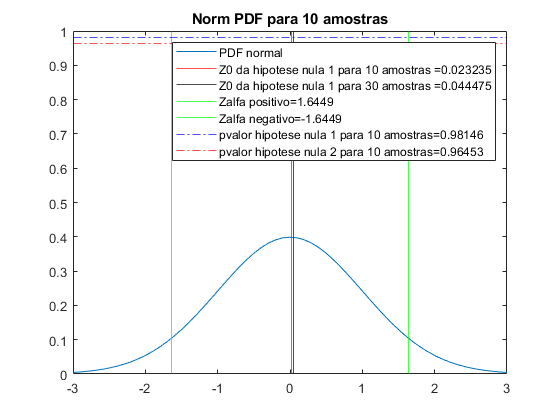

x = -3:.1:3;
pdf_normal = pdf(pd,x);
figure
plot(x,pdf_normal)
xline(z0_1_10, "color", "r")
xline(z0_1_30, "color", "black")
xline(z_alfa, "color", "g")
xline(-z_alfa, "color", "g")
yline(p_valor_1_10, "color", "b", "lineStyle", "-.")
yline(p_valor_1_30, "color", "r", "lineStyle", "-.")
title("Norm PDF para 10 amostras")
legend({"PDF normal", "Z0 da hipotese nula 1 para 10 amostras ="+z0_1_10, ...
    "Z0 da hipotese nula 1 para 30 amostras ="+z0_1_30, ...
    "Zalfa positivo="+z_alfa, ...
    "Zalfa negativo="+-z_alfa, ...
    "pvalor hipotese nula 1 para 10 amostras="+p_valor_1_10, ...
    "pvalor hipotese nula 2 para 10 amostras="+p_valor_1_30})

Analisando o gráfico da normPDF para 10 amostras chega-se nas seguintes conclusões:

- Observa-se que $-z_{\alpha } <z_0 <z_{\alpha }$, portanto a hipótese nula não foi rejeitada e podemos afirmar que $\mu_{1\;} =\mu_2$.

- p_valores muito altos e muito maiores que $\alpha$ indica que o teste não é confiável,

Veremos a seguir com a escolha de 30 amostras como isso afetará nos resultados.

Plotando a PDF para 30 amostras:

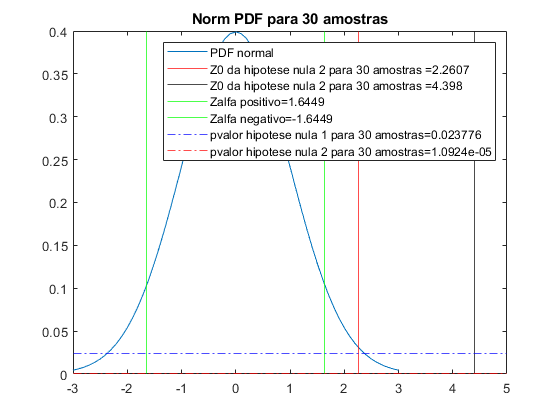

%pd = makedist('Normal')
x = -3:.1:3;
pdf_normal = pdf(pd,x);
figure
plot(x,pdf_normal)
xline(z0_2_10, "color", "r")
xline(z0_2_30, "color", "black")
xline(z_alfa, "color", "g")
xline(-z_alfa, "color", "g")
yline(p_valor_2_10, "color", "b", "lineStyle", "-.")
yline(p_valor_2_30, "color", "r", "lineStyle", "-.")
title("Norm PDF para 30 amostras")
legend({"PDF normal", "Z0 da hipotese nula 2 para 30 amostras ="+z0_2_10, ...
    "Z0 da hipotese nula 2 para 30 amostras ="+z0_2_30, ...
    "Zalfa positivo="+z_alfa, ...
    "Zalfa negativo="+-z_alfa, ...
    "pvalor hipotese nula 1 para 30 amostras="+p_valor_2_10, ...
    "pvalor hipotese nula 2 para 30 amostras="+p_valor_2_30})

Agora, para 30 amostras, observa-se que $z_0 >z_{\alpha }$, logo, estatisticamente podemos concluir que $\mu_{3\;} \not= \mu_3$.

Ademais, nota-se que os p_valores são menores que $\alpha$, logo, pode-se concluir que este teste é extremamente confiável.

#### 2) Selecione novos segmentos de dados X1, X2 e X3 para fazer o teste de variâ ncia, de modo que as populações de X1 e X2 tenham a mesma variância enquanto X1 e X3 tenham variâ ncia diferente, com = 5%. Deve-se plote os dados utilizados em cada segmento, a pdf das populações usadas no teste com o valor da estatística de teste, o p-valor.

#### Use o mesmo número de amostras do item 1.

Resposta:

Na questão 1, foram utilizados 10 e 30 amostar para analisar o efeito da escolha do número de amostras na confiança do teste.

Dessa forma, segue a seleção de X1, X2 e X3 conforme solicitado.

X1 = datasample(Y(1106:2000), 800);
X2 = datasample(Y(1106:2000), 800);
X3 = datasample(Y(1:900), 800);

std_X1_10 = std(datasample(X1, 10))

std_X1_10 = 0.2638

std_X1_30 = std(datasample(X1, 30))

std_X1_30 = 0.2270

std_X2_10 = std(datasample(X2, 10))

std_X2_10 = 0.1525

std_X2_30 = std(datasample(X2, 30))

std_X2_30 = 0.2052

std_X3_10 = std(datasample(X3, 10))

std_X3_10 = 0.2385

std_X3_30 = std(datasample(X3, 30))

std_X3_30 = 0.2234

Agora, será calculado os pontos de rejeição em alfa na distribuição padrão:

alfa = 0.025; % alfa /2
f_alfa_10 = finv(1 - alfa, 10-1,10-1)

f_alfa_10 = 4.0260

f_alfa_30 = finv(1 - alfa, 30 - 1, 30 - 1)

f_alfa_30 = 2.1010

Considerando que que as hipóteses nulas são $H_0 :\sigma_1^2 -\sigma_2^2$=0 e $H_0 :\sigma_1^2 -\sigma_3^2 =0$, serão calculados o $f_0$ para 10 e 30 amostras.

Para 10 amostras:

f0_1_10 = min(std_X1_10^2, std_X2_10^2) / max(std_X1_10^2, std_X2_10^2)

f0_1_10 = 0.3342

f0_2_10 = min(std_X1_10^2, std_X3_10^2) / max(std_X1_10^2, std_X3_10^2)

f0_2_10 = 0.8172

Para 30 amostras:

f0_1_30 = min(std_X1_30^2, std_X2_30^2) / max(std_X1_30^2, std_X2_50^2)

f0_1_30 = 0.8171

f0_2_30 = min(std_X1_30^2, std_X3_30^2) / max(std_X1_30^2, std_X3_30^2)

f0_2_30 = 0.9683

Verificação das hipóteses nulas:


$$H_0 :\sigma_1^2 -\sigma_2^2 =0$$


if f0_1_10 > f_alfa_10
disp("H_0_1 para 10 amostras Rejeitada!")
else
disp("H_0_1 para 10 amostras não rejeitada!")
end

H_0_1 para 10 amostras não rejeitada!


if f0_1_30 > f_alfa_30
disp("H_0_1 para 50 amostras Rejeitada!")
else
disp("H_0_1 para 50 amostras não rejeitada!")
end

H_0_1 para 50 amostras não rejeitada!


Observa-se que ambas a hipóteses não são rejeitadas, portanto, podemos concluir que as variâncias são estatisticamente iguais!

Agora, para $H_0 :\sigma_1^2 -\sigma_3^2 =0$

if f0_2_10 > f_alfa_10
disp("H_0_2 para 10 amostras Rejeitada!")
else
disp("H_0_2 para 10 amostras não rejeitada!")
end

H_0_2 para 10 amostras não rejeitada!



if f0_2_30 > f_alfa_30
disp("H_0_2 para 30 amostras Rejeitada!")
else
disp("H_0_2 para 30 amostras não rejeitada!")
end

H_0_2 para 30 amostras não rejeitada!


Novamente, se que ambas a hipóteses não são rejeitadas isto significa que as variâncias são estatisticamente iguais.

Cálculo dos p_valores:

Para 10 amostras:

p_valor_1_10 = (1 - fcdf(f0_1_10, 10 - 1, 10 - 1))

p_valor_1_10 = 0.9409

p_valor_2_10 = (1 - fcdf(f0_2_10, 10 - 1, 10 - 1))

p_valor_2_10 = 0.6157

Para 30 amostras:

p_valor_1_30 = 1 - fcdf(f0_1_30, 30 - 1, 30 - 1)

p_valor_1_30 = 0.7049

p_valor_2_30 = 1 - fcdf(f0_2_30, 30 - 1, 30 - 1)

p_valor_2_30 = 0.5343

Plotando a PDF f padrao e os p_valores para 10 amostras.

pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


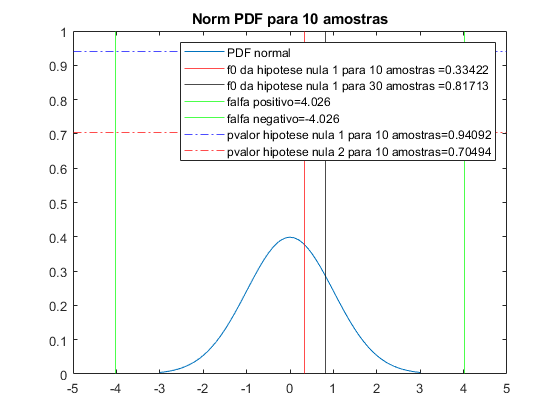

x = -3:.1:3;
pdf_normal = pdf(pd,x);
figure
plot(x,pdf_normal)
xline(f0_1_10, "color", "r")
xline(f0_1_30, "color", "black")
xline(f_alfa_10, "color", "g")
xline(-f_alfa_10, "color", "g")
yline(p_valor_1_10, "color", "b", "lineStyle", "-.")
yline(p_valor_1_30, "color", "r", "lineStyle", "-.")
title("Norm PDF para 10 amostras")
legend({"PDF normal", "f0 da hipotese nula 1 para 10 amostras ="+f0_1_10, ...
    "f0 da hipotese nula 1 para 30 amostras ="+f0_1_30, ...
    "falfa positivo="+f_alfa_10, ...
    "falfa negativo="+-f_alfa_10, ...
    "pvalor hipotese nula 1 para 10 amostras="+p_valor_1_10, ...
    "pvalor hipotese nula 2 para 10 amostras="+p_valor_1_30})

Plotando a PDF f padrao e os p_valores para 30 amostras.

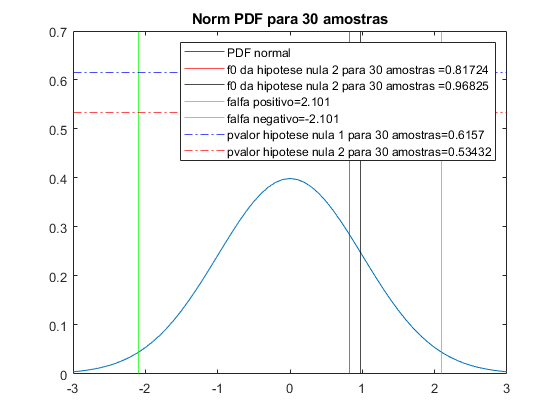

%pd = makedist('Normal')
x = -3:.1:3;
pdf_normal = pdf(pd,x);
figure
plot(x,pdf_normal)
xline(f0_2_10, "color", "r")
xline(f0_2_30, "color", "black")
xline(f_alfa_30, "color", "g")
xline(-f_alfa_30, "color", "g")
yline(p_valor_2_10, "color", "b", "lineStyle", "-.")
yline(p_valor_2_30, "color", "r", "lineStyle", "-.")
title("Norm PDF para 30 amostras")
legend({"PDF normal", "f0 da hipotese nula 2 para 30 amostras ="+f0_2_10, ...
    "f0 da hipotese nula 2 para 30 amostras ="+f0_2_30, ...
    "falfa positivo="+f_alfa_30, ...
    "falfa negativo="+-f_alfa_30, ...
    "pvalor hipotese nula 1 para 30 amostras="+p_valor_2_10, ...
    "pvalor hipotese nula 2 para 30 amostras="+p_valor_2_30})

Em ambos os casos, para 10 e 30 amostras, temos que as hipóteses nulas não foram rejeitas e isto indica que estatistiscamente $\sigma_1^2 -\sigma_2^2 =\sigma_1^2 -\sigma_3^2 =0\ldotp$Entretanto, os p_valores tendem a ficar muito próximos ou até maiores que 1-alfa, e isso significa que esses testes não possuem um nível de confiabilidade aceitável.

#### 3) Um professor deseja usar duas provas em suas aulas no próximo ano. Este ano, ela aplica os dois exames aos alunos. Ela quer saber se os exames são igualmente difíceis e quer verificar isso observando as diferenças entre as notas. Se a diferença média entre as notas dos alunos for “suficientemente próxima” de zero, ela chegará à conclusão prática de que os exames são igualmente difíceis. Analise os dados abaixo e faça um teste pareado para verificar se o grau de dificuldade é similar.

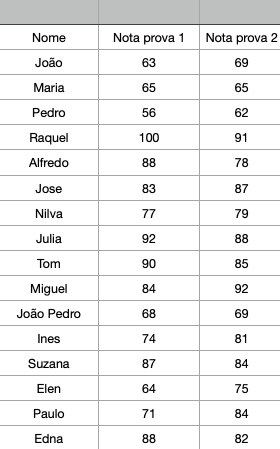

Resposta:

nota_1=[63 65 56 100 88 83 77 92 90 84 68 74 87 64 71 88];
nota_2=[69 65 62 91 78 87 79 88 85 92 69 81 84 75 84 82];
dif=(nota_2-nota_1);
media_dif=mean(dif)

media_dif = 1.3125

sd=var(dif)

sd = 49.0292

alfa=0.05

alfa = 0.0500

t_alfa_005=tinv(1-alfa/2,16-1)

t_alfa_005 = 2.1314

t0_1=(media_dif-0)/(sd/sqrt(length(dif)))

t0_1 = 0.1071

if (t0_1<-t_alfa_005)||(t0_1>t_alfa_005)
    disp('H0: μd=0 Rejeitada !');
else 
    disp('H0: μd=0 Não Rejeitada !');
end

H0: μd=0 Não Rejeitada !


Agora, utlizando alfa = 0,1 para testar se a hipótese será rejeitada.

alfa_2=0.1

alfa_2 = 0.1000

t_alfa_01=tinv(1-alfa_2/2,16-1)

t_alfa_01 = 1.7531

t0_2=(media_dif-0)/(sd/sqrt(16))

t0_2 = 0.1071

if (t0_2<-t_alfa_01)||(t0_2>t_alfa_01)
    disp('H0: μd=0 Rejeitada !');
else 
    disp('H0: μd=0 Não Rejeitada !');
end

H0: μd=0 Não Rejeitada !


`Em ambos os testes, não foi rejeitado, portanto pode-se verificar que não há evidências suficientes para rejeitar a hipótese que os exames são igualmente difíceis.`

`Agora calculemos o p-valor para este teste:`

pval_teste1 = tcdf(t0_1, length(dif)) 

pval_teste1 = 0.5420

Concluí-se, portanto, que além da hipótese nula não ser rejeitada ainda temo um p_valor muito maior que alfa. Isto indica que o teste mostra que não podemos rejeitar a hipótese de que os exame são igualmente difíceis, mas não podemos inferir que o teste é completamente confiável.